# Discovering Phased Array Toolbox

https://www.mathworks.com/help/releases/R2025b/antenna/ug/model-and-analyze-dual-polarized-patchmicrostrip-antenna.html

c       = physconst('LightSpeed');
fc      = 2.4e9;
lambda  = freq2wavelen(fc,c);
hpbw    = 45;

- Array specifications

numRows = 8;
numCols = 8;
lattice = "rectangular";

- Define the radiating element from the catalog

%radiatingElt = phased.IsotropicAntennaElement("BackBaffled",true);
radiatingElt = phased.CosineAntennaElement("CosinePower",[8,8]);
%radiatingElt = phased.GaussianAntennaElement("Beamwidth",hpbw);

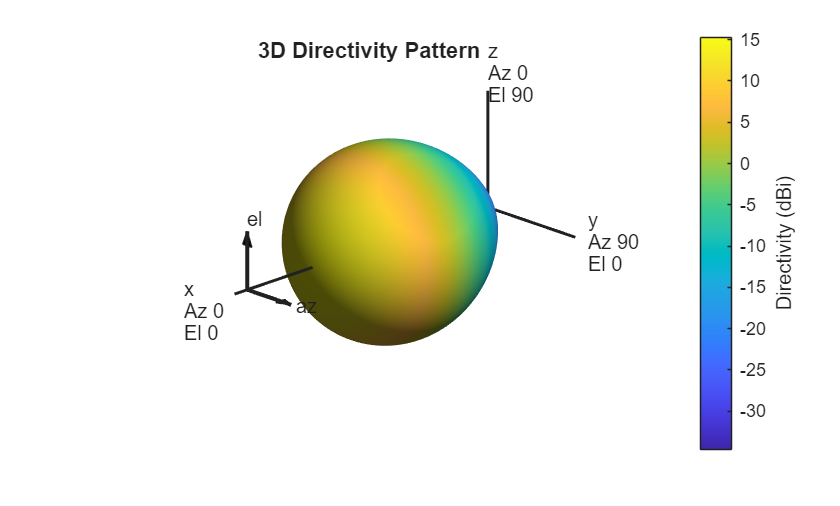

figure
pattern(radiatingElt,fc)

- Define the array

AESA = phased.URA(...
    "Element",radiatingElt,...
    "Size",[numRows, numCols],...
    "ElementSpacing",lambda/2, ...
    "Lattice","Triangular");

[bw, ang] = beamwidth(AESA,fc)

bw = 11.9600

ang =    -5.9800    5.9800


radiatingEltPos = AESA.getElementPosition;

AF = 20*log10(AESA.getNumElements)

AF = 36.1236

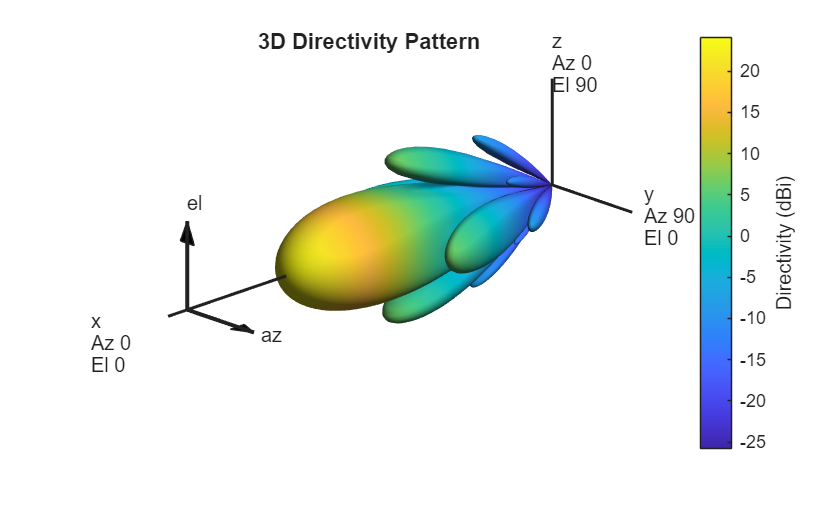

figure
pattern (AESA,fc)

### Use a Custom Antenna Element

- Create a customAntennaElement

radiatingElt = phased.CustomAntennaElement;

We now need to specify the az-el angles and fill the Magnitude and Phase pattern from the radiating element created in Antenna toolbox

load dualPolarizedAntennaDesign.mat;

- adjust meshing

figure;
mesh(dualPolarizedAntenna,...
    'MaxEdgeLength',0.006,...
    'MinEdgeLength',0.004,...
    'GrowthRate',0.7);

Get pattern (combined H-V) of the dual polarized antenna 

DPA_Mag_Pattern = pattern(dualPolarizedAntenna,fc, -180:180, -90:90, 'Type','directivity')

%DPA_Phase_Pattern = pattern(dualPolarizedAntenna,fc, -180:180, -90:90, 'Type','phase')
radiatingElt.MagnitudePattern = antennaPattern
AESA = phased.URA(...
    "Element",radiatingElt,...
    "Size",[numRows, numCols],...
    "ElementSpacing",lambda/2, ...
    "Lattice","Triangular");

figure
pattern (AESA,fc)

pattern(dualPolarizedAntenna,fc, -180:180, -90:90, 'Type','directivity')